# Etz Hayim Network

# Subversive Kuramoto Model

clc
clear
close all
tic

## Sources

📗Shyfrin, E. (2019). From infinity to man: The fundamental ideas of kabbalah within the framework of information theory and Quantum physics. White Raven Publishing.

## Background

### Diagram

        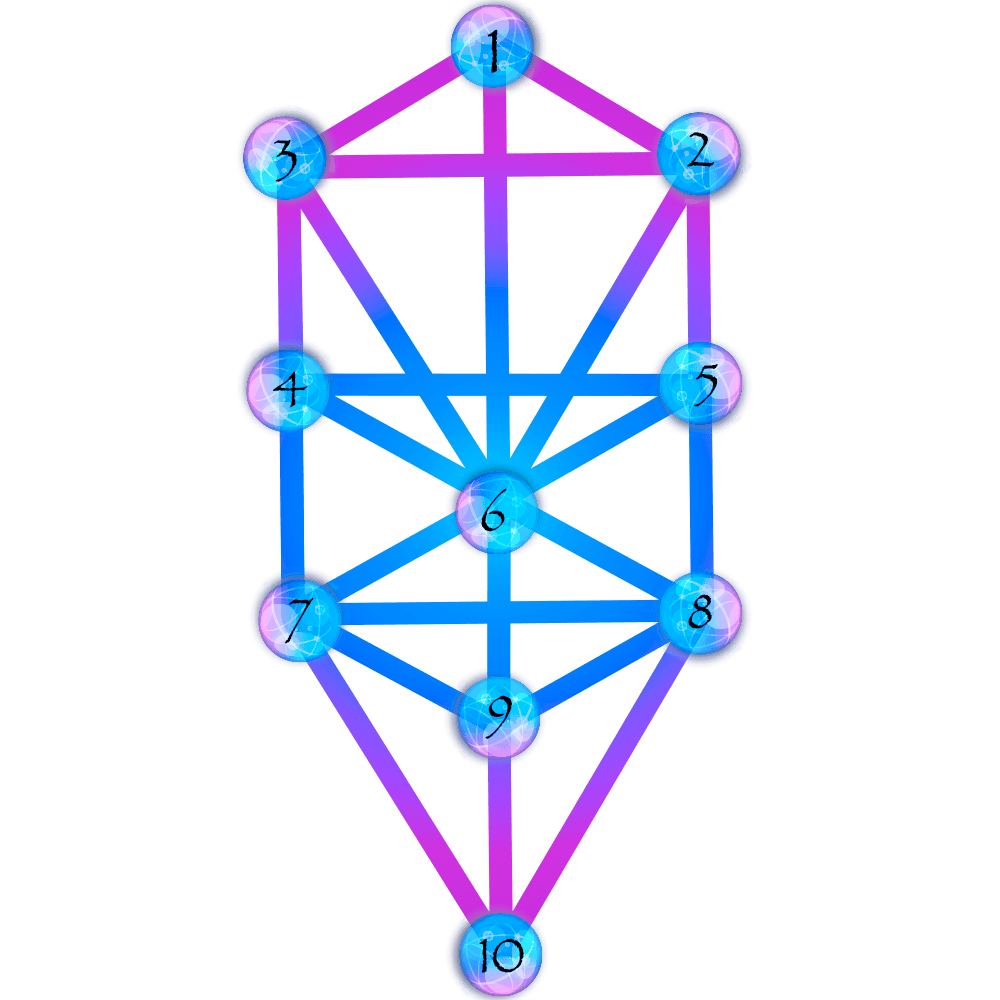

- *Keter *= the Crown

- *Chochma* = wisdom

- *Binah* = understanding

- *Chesed* = kindness, love, expansion

- *Gevurah* = might, judgement, power, contraction

- *Tiferet* = beauty 

- *Netzach* = victory

- *Hod* = splendor

- *Yesod* = foundation

- *Malchut* = kingdom  

## Create Tree of Life Network

#### Node Names

nodes = {'Keter' 'Chochma' 'Binah' 'Chesed' 'Gevurah' ...
    'Tiferet' 'Netzach' 'Hod' 'Yesod' 'Malchut'}';

#### Adjacency Matrix

A = [0 1 1 0 1 0 0 0 0 0; ...
     1 0 1 0 1 1 0 0 0 0; ...
     1 1 0 1 1 0 0 0 0 0; ...
     0 0 1 0 1 1 0 1 0 0; ...
     1 1 1 1 0 1 1 1 1 0; ...
     0 1 0 1 1 0 1 0 0 0; ...
     0 0 0 0 1 1 0 1 1 1; ...
     0 0 0 1 1 0 1 0 1 1; ...
     0 0 0 0 1 0 1 1 0 1; ...
     0 0 0 0 0 0 1 1 1 0];

## Create graph

G_nodes = graph(A,nodes);
G = graph(A)

G =   graph with properties:

    Edges: [22×2 table]
    Nodes: [10×0 table]


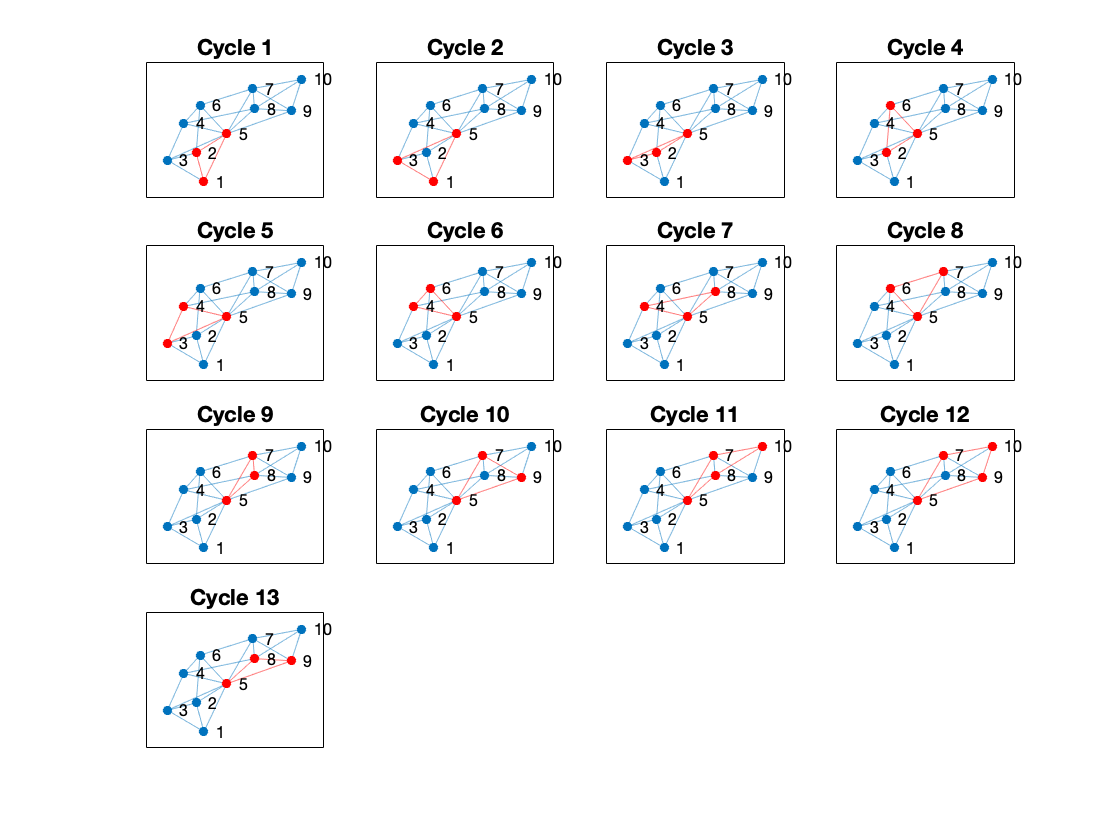

[cycles,edgecycles] = cyclebasis(G);
figure
tiledlayout flow
for k = 1:length(cycles)
    nexttile
    highlight(plot(G),cycles{k},'Edges',edgecycles{k},'EdgeColor','r','NodeColor','r')
    title("Cycle " + k)
end

#### Node Names

nodes = {'Keter' 'Chochma' 'Binah' 'Chesed' 'Gevurah' ...
    'Tiferet' 'Netzach' 'Hod' 'Yesod' 'Malchut'}';

#### Adjacency Matrix

A = [0 1 1 0 0 1 0 0 0 0; ...
     1 0 1 0 1 1 0 0 0 0; ...
     1 1 0 1 0 1 0 0 0 0; ...
     0 0 1 0 1 1 1 0 0 0; ...
     0 1 0 1 0 1 0 1 0 0; ...
     1 1 1 1 1 0 1 1 1 1; ...
     0 0 0 1 0 1 0 1 1 1; ...
     0 0 0 0 1 1 1 0 1 1; ...
     0 0 0 0 0 1 1 1 0 1; ...
     0 0 0 0 0 1 1 1 1 0];
     

## Create graph

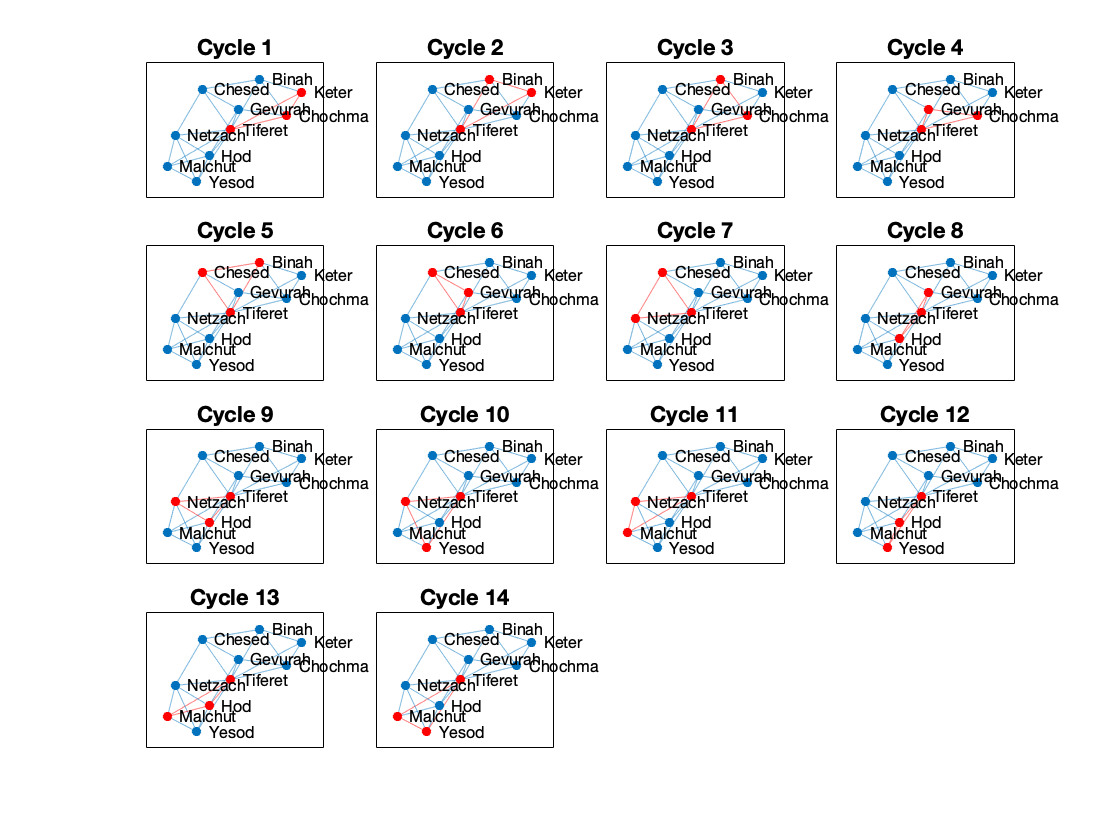

G = graph(A,nodes);
[cycles,edgecycles] = cyclebasis(G);
figure
tiledlayout flow
for k = 1:length(cycles)
    nexttile
    highlight(plot(G),cycles{k},'Edges',edgecycles{k},'EdgeColor','r','NodeColor','r')
    title("Cycle " + k)
end

#### Plot the graph

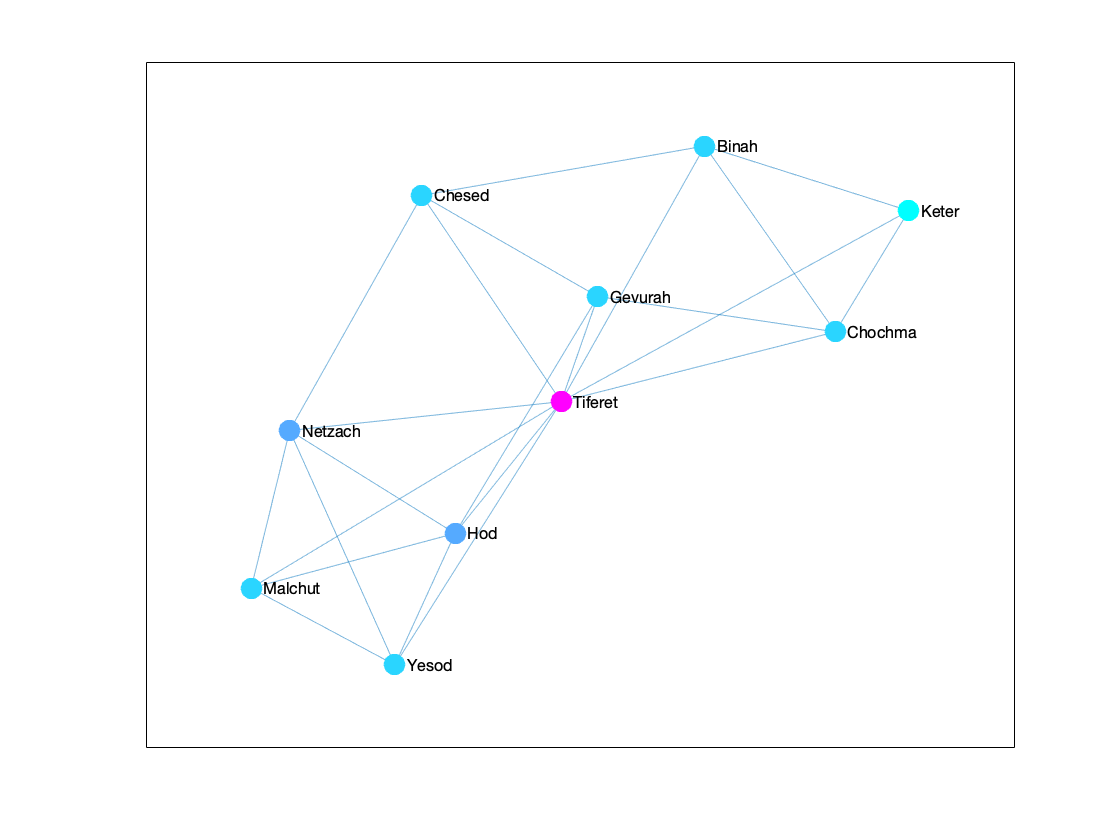

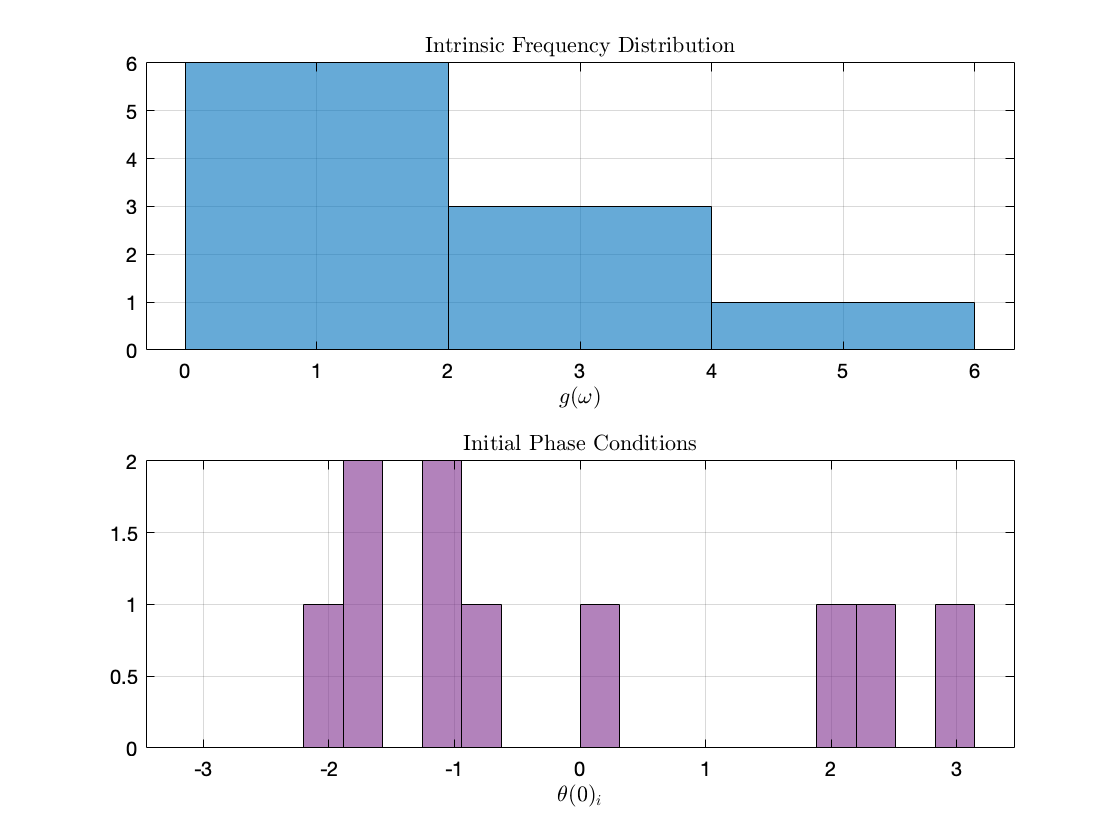

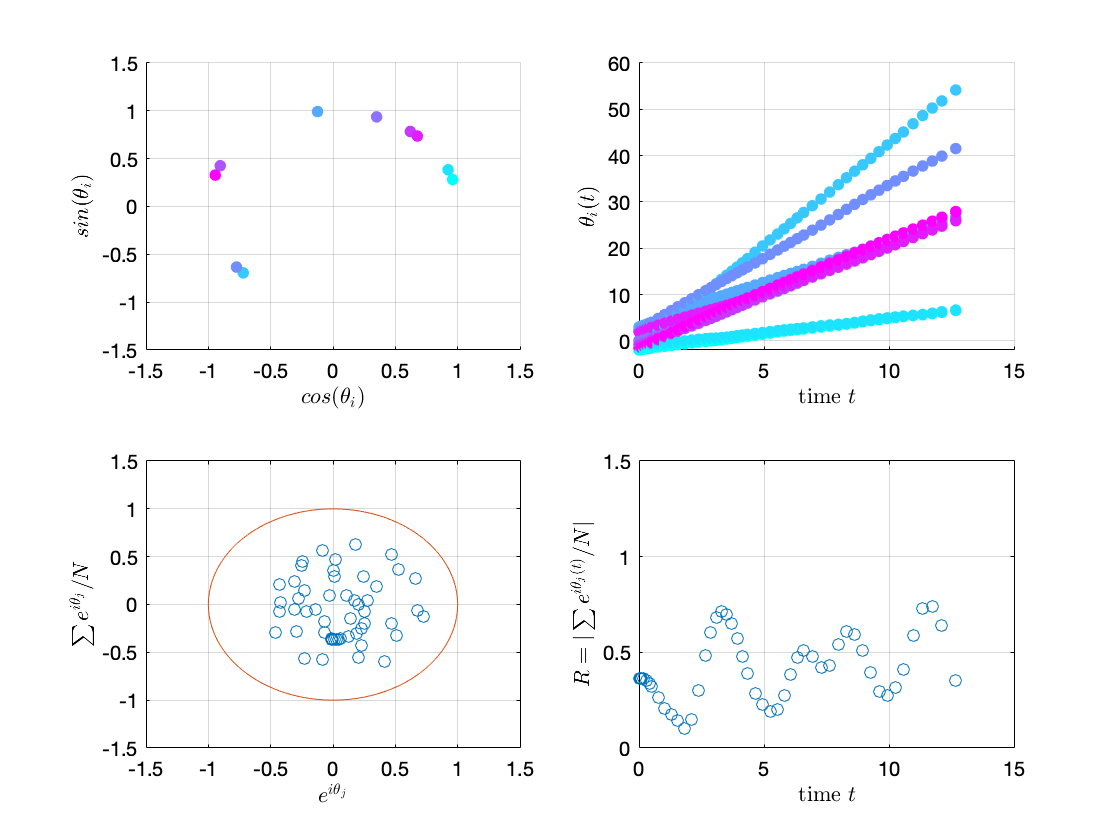

figure
whitebg([1 1 1])
set(gcf,'inverthardcopy','off')
h = plot(G);
colormap cool
nColors = degree(G);
h.NodeCData= nColors;
h.MarkerSize = 10;